# **Ejercicio 1**

## Problema T6_7.1. Primera y segunda derivadas en puntos no equiespaciados

clear, clc % Limpieza del entorno de trabajo

a) Escribir una función en Matlab que calcule la primera y segunda derivada de una función que viene dada por un conjunto de puntos discretos desigualmente espaciados.

- Véase PyDerDes.m

b) Utiliza la función creada para resolver el siguiente problema. En la siguiente tabla se da la posición $\left(x,y\right)$ de los coches de una montaña rusa en función del tiempo $t$.

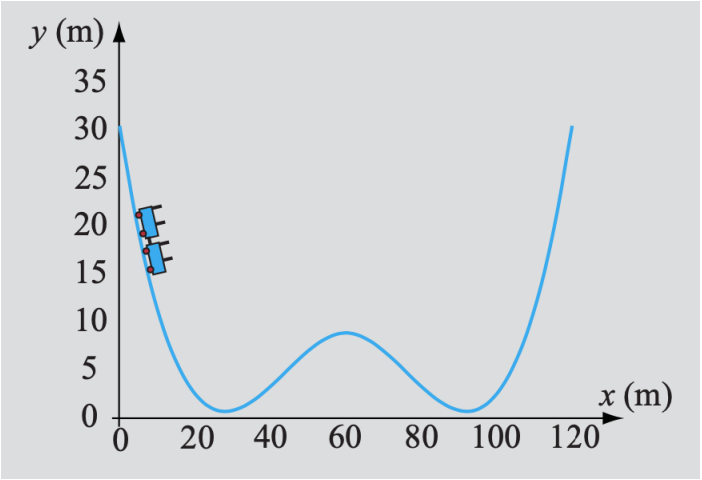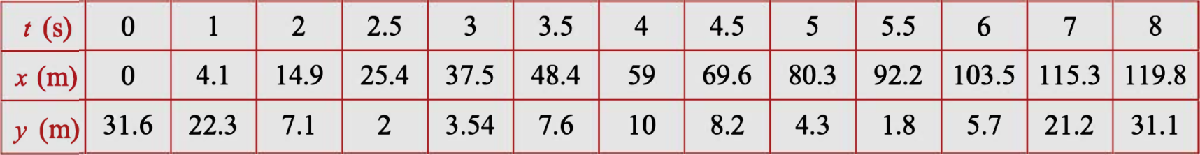

t = [0, 1, 2, 2.5, 3, 3.5, 4, 4.5, 5, 5.5, 6, 7, 8];
x = [0, 4.1, 14.9, 25.4, 37.5, 48.4, 59, 69.6, 80.3, 92.2, 103.5, 115.3, 119.8];
y = [31.6, 22.3, 7.1, 2, 3.54, 7.6, 10, 8.2, 4.3, 1.8, 5.7, 21.2, 31.1];

La velocidad está dada por: 


$$v=\sqrt{{v_x }^2 +{v_y }^2 }$$
            
$$v_x =\frac{\textrm{dx}}{\textrm{dt}}$$
            
$$v_y =\frac{\textrm{dy}}{\textrm{dt}}$$


La acelaración está dada por:


$$a=\sqrt{{a_x }^2 +{a_y }^2 }$$
            
$$a_x =\frac{d^2 x}{\textrm{dt}}$$
            
$$a_y =\frac{d^2 y}{\textrm{dt}}$$


b.1) Calcula la velocidad y la aceleración para cada instante �. Da el resultado en una tabla donde las columnas sean: t(s), x(m), y(m), v(m/s), a(m/s²)

Usando PySDerDes obtenemos los valores de la velocidad y aceleración en los puntos dato

[xd, xdd] = PySDerDes(t, x);
[yd, ydd] = PySDerDes(t, y);
v = sqrt(xd.^2+yd.^2);
a = sqrt(xdd.^2+ydd.^2);

Guardamos en una tabla los resultados obtenidos

res = table( ...
    num2str(t', '%.2f'), ...
    num2str(x', '%.2f'), ...
    num2str(y', '%.2f'),...
    num2str(v', '%.4f'), ...
    num2str(a', '%.4f'), ...
    VariableNames={'t(s)', 'x(m)', 'y(m)', 'v(m/s)', 'a(m/s²)'});
disp(res)

    t(s)     x(m)     y(m)     v(m/s)     a(m/s²)
    ____    ______    _____    _______    _______

    0.00      0.00    31.60     6.3941    21.0394
    1.00      4.10    22.30    14.3375    14.3375
    2.00     14.90     7.10    21.2268    21.2268
    2.50     25.40     2.00    22.8787    22.8787
    3.00     37.50     3.54    23.6719    23.6719
    3.50     48.40     7.60    22.4495    22.4495
    4.00     59.00    10.00    21.2085    21.2085
    4.50     69.60     8.20    22.0495    22.0495
    5.00     80.30     4.30    23.4887    23.4887
    5.50     92.20     1.80    23.2422    23.2422
    6.00    103.50     5.70    21.6441    21.6441
    7.00    115.30    21.20    15.0901     9.2005
    8.00    119.80    31.10     7.1507    24.6702



b.2) Dibuja (tres gráficas en la misma página) las gráficas de $y=f\left(x\right)$    $v=v\left(t\right)$    $a=a\left(t\right)$

Límites de las gráficas

l1_x = min(x); l2_x = max(x);
xx = linspace(l1_x, l2_x);
l1_t = min(t); l2_t = max(t);
tt = linspace(l1_t, l2_t);

Realizamos 3 subplots para tener las gráficas en la misma página

Subplot de posición (x, y)

subplot(3, 1, 1)
plot(x, y,'b.', MarkerSize=12);
pp = spline(x, y);
yy = ppval(pp, xx);
hold on
plot(xx, yy, 'b-')
title('Posición m')
xlabel('x'); ylabel('y(x)')
hold off

Subplot de velocidad v(t)

subplot(3, 1, 2)
plot(t, v, 'r.', MarkerSize=12)
pp = spline(t, v);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'r-')
title('Velocidad m/s')
xlabel('t'); ylabel('v(t)')
hold off

Subplot de aceleración a(t)

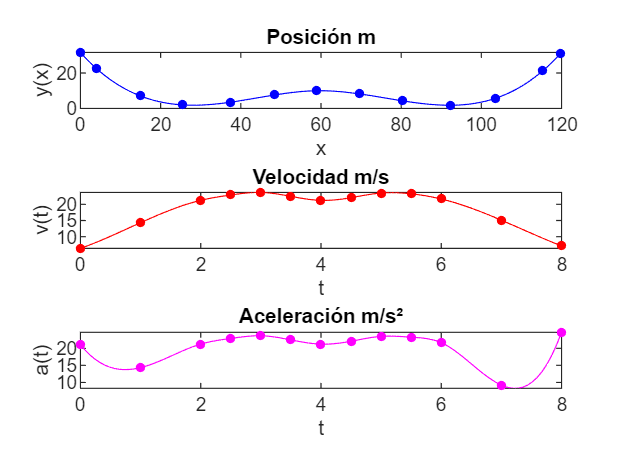

subplot(3, 1, 3)
plot(t, a, 'm.', MarkerSize=12)
pp = spline(t, a);
yy = ppval(pp, tt);
hold on
plot(tt, yy, 'm-')
title('Aceleración m/s²')
xlabel('t'); ylabel('a(t)')
hold off